clear; close all;
trial = 42

trial = 42

addpath("utils/")
dataPath = sprintf('DataSets/LapTrials/test%d.csv', trial);
[~, timedelta, data] = parseDataSet(dataPath);
dt = mean(timedelta) * 1e-9;
xpos = data(:,22);
ypos = data(:,23);
theta = data(:,24);
linvel = data(:, 15); 
angvel = data(:,18);
pitch = data(:,1); 

% Velocity Profile Per Lap in Trial
results = find_all_laps(xpos, ypos, theta, 800, 0.01, 6);
results.laptimes;
numlapsfound = length(results.lap_indices)

numlapsfound = 2

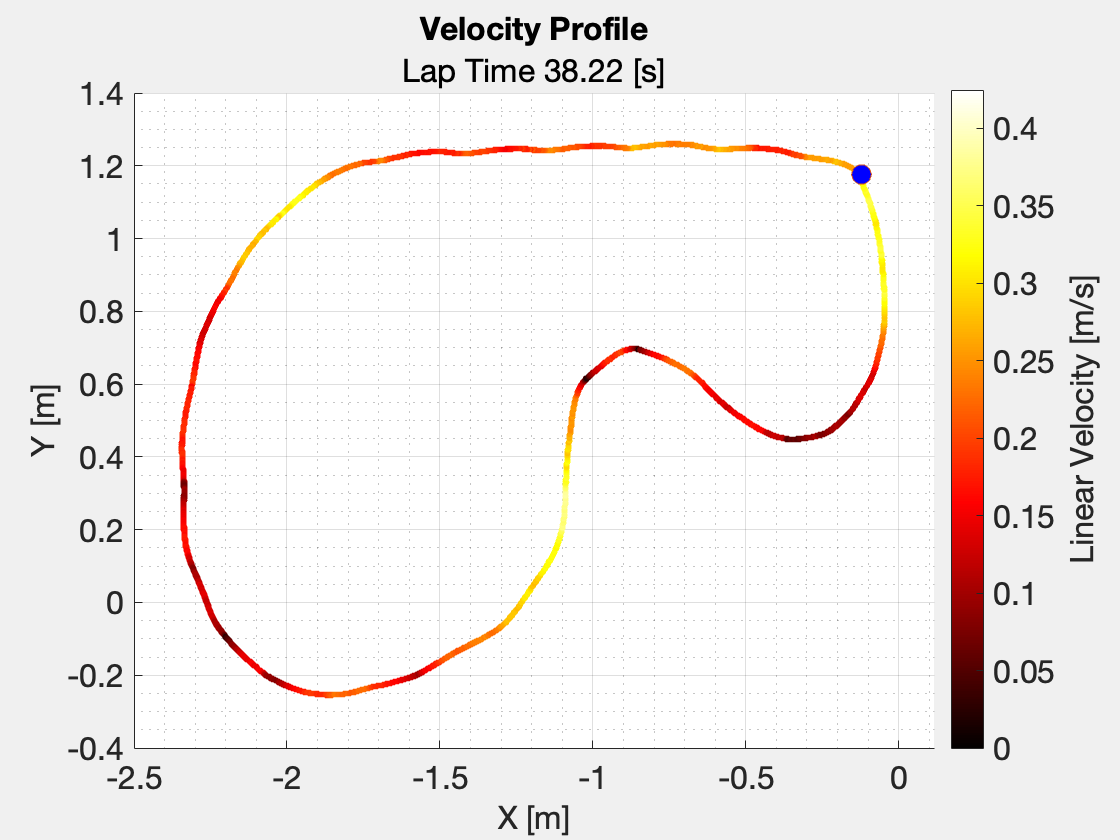

lapidx =1;

start = results.lap_indices(lapidx, 1);
stop = results.lap_indices(lapidx, 2);
laptime = round(cell2mat(results.laptimes(lapidx)),2);
lap_xpos = xpos(start:stop);
lap_ypos = ypos(start:stop);
lap_linvel = linvel(start:stop);
heading = theta(start) - deg2rad(150);
R = [cos(-heading), -sin(-heading); 
    sin(-heading),  cos(-heading)];
lap_aligned = (R * [lap_xpos'; lap_ypos'])';


fig = figure;
scatter(lap_aligned(:,1),lap_aligned(:,2), 10,lap_linvel, 'filled');
hold on;
plot(lap_aligned(1,1), lap_aligned(1,2),"Marker", 'o','MarkerFaceColor','b', 'MarkerSize',10);
hold off
colormap("hot");
xlabel('X [m]', 'FontSize', 16);
ylabel('Y [m]', 'FontSize', 16);
subtitle = sprintf('Lap Time %0.2f [s]',laptime);
plotTitle = "Velocity Profile";
title(plotTitle, subtitle, 'FontSize', 18);
cb =colorbar();
ylabel(cb, 'Linear Velocity [m/s]');
maxvel = max(lap_linvel);
clim([0,1.1*maxvel]);
axis padded; grid on; grid minor; 
fontsize(16, "points");
set(gcf,'Visible', 'on')
folderpath = fullfile("..", "Docs", "Y3Report", "Images", "Graphs", filesep);
filepath = fullfile(folderpath, plotTitle+"_"+num2str(trial)+"_"+num2str(lapidx)+   ".pdf");
set(gcf,'Visible', 'on')

exportgraphics(fig, filepath)

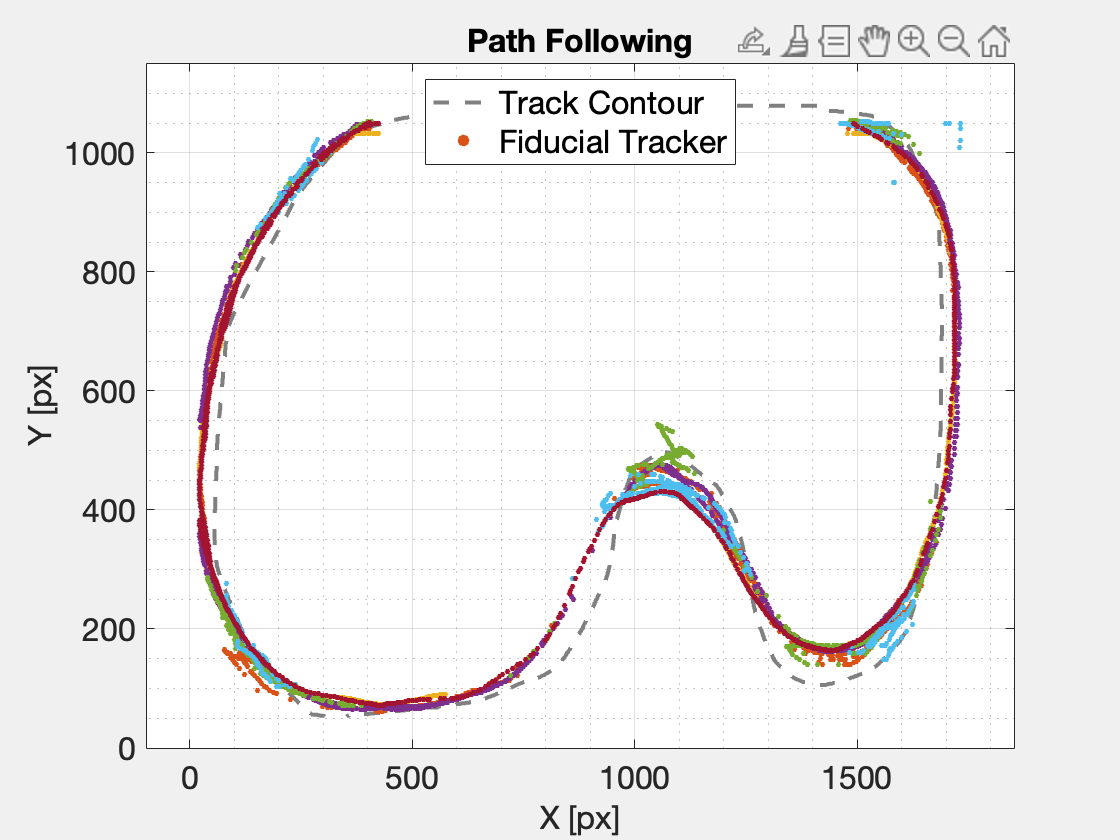

% Tracker Top Down
trials = [26, 31,33, 34,40,41];
B = readtable('DataSets/track.csv');
fig = figure;
plot(B.Var1, B.Var2, 'LineWidth',2,'LineStyle','--', 'Color',[0.5, 0.5, 0.5]);
hold on;
for i=1:length(trials)
    trial = trials(i);
    filename = sprintf("DataSets/LapTrials/tracked%d.csv", trial);
    T = readtable(filename); 
    xpos = filloutliers(T.Var2,"clip");
    ypos =  filloutliers(T.Var3, "clip");
    xpos = smoothdata(xpos, 'movmedian', 5);
    ypos = smoothdata(ypos, 'movmedian', 5);
    scatter(xpos(1:end-1), ypos(1:end-1), 8,'filled');
end
axis padded;
xlabel('X [px]');
ylabel('Y [px]');
legend('Track Contour', 'Fiducial Tracker', Location='north');
plotTitle = 'Path Following';
title(plotTitle, 'FontSize',18);
fontsize(16, "points");
grid on; grid minor;
folderpath = fullfile("..", "Docs", "Y3Report", "Images", "Graphs", filesep);
filepath = fullfile(folderpath, plotTitle +".pdf");
set(gcf,'Visible', 'on');
exportgraphics(fig, filepath)

function results = find_all_laps(xpos, ypos, theta, min_samples, tolerance, min_displacment)
    if nargin < 4 || isempty(min_samples)
        min_samples = 800;
    end
    if nargin < 5 || isempty(tolerance)
        tolerance = 0.2;
    end
    if nargin < 6 || isempty(min_displacment)
        min_displacment = 3; % in meters
    end

    % Precompute cumulative travel distance (along the path)
    ds = sqrt(diff(xpos).^2 + diff(ypos).^2);
    cum_distance = [0; cumsum(ds)];
    
    % Prepare output structure
    results.lap_indices = [];           % Each row: [start_index, closure_index]
    results.lap_offsets = {};           % Cell array of [x_offset, y_offset] relative to lap start
    results.lap_offsets_aligned = {};   % Cell array after aligning (rotating) based on heading
    results.laptimes = {};
    N = length(xpos);
    i = 1;
    
    while i < N - min_samples
        % Define the starting point and heading for the candidate lap.
        start_point = [xpos(i), ypos(i)];
        found = false;
        
        % Look for a candidate closure point j at least min_samples away.
        for j = i + min_samples : N
            % Ensure the robot has traveled a minimum cumulative displacement
            if (cum_distance(j) - cum_distance(i)) < min_displacment
                continue;
            end
            if(cum_distance(j) - cum_distance(i)) > 8
               continue;
            end
            current_point = [xpos(j), ypos(j)];
            dist = norm(current_point - start_point);
            if dist < tolerance
                % Loop closure detected.
                results.lap_indices = [results.lap_indices; i, j]; 
                
                % Compute raw offsets for the lap (translation relative to starting point).
                lap_x = xpos(i:j) - xpos(i);
                lap_y = ypos(i:j) - ypos(i);
                results.lap_offsets{end+1} = [lap_x, lap_y];
                % Jump ahead to j to prevent overlapping detections.
                i = j;
                found = true;
                results.laptimes{end+1} = round((results.lap_indices(end,2) - results.lap_indices(end,1)) * 0.01, 2);
                break;
            end
        end
        
        if ~found
            i = i + 1;
        end
    end
end